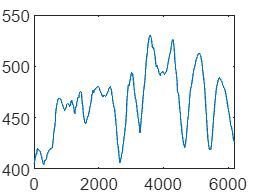

close all
clear all

all_points = readmatrix('./paths/przyk3.txt');
plot(all_points(:,1), all_points(:, 2))

x_lim_orig = xlim;
y_lim_orig = ylim;

n = 15;

X = all_points(floor(linspace(1, size(all_points, 1), n)), 1);
Y = all_points(floor(linspace(1, size(all_points, 1), n)), 2);

A = zeros(n, n);
A(:, 1) = 1;

for i = 2:n
    A(:,i) = X.^(i-1);
end

b = Y;
a = A\b;

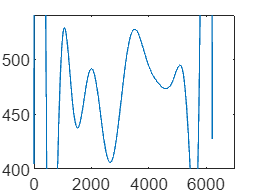



m = n * 100; % points in the interpolation
X_app = all_points(floor(linspace(1, size(all_points, 1), m)), 1);

X_pow = zeros(m, n); % 1 x1 x1^2 ... \ ... 1 x2 x2^2 ... \ ...
X_pow(:, 1) = 1;

for i = 2:n
    X_pow(:,i) = X_app.^(i-1);
end

Y_app = X_pow * a; 


plot(X_app, Y_app)
xlim(x_lim_orig)
ylim(y_lim_orig)

close all
clear all


all_points = readmatrix('./paths/przyk3.txt');
plot(all_points(:,1), all_points(:, 2))

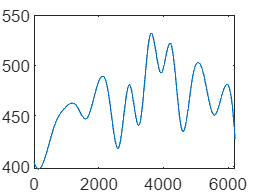

x_lim_orig = xlim;
y_lim_orig = ylim;

n = 20; % number of points
% number of functions -> n-1

x = all_points(floor(linspace(1, size(all_points, 1), n)), 1);
y = all_points(floor(linspace(1, size(all_points, 1), n)), 2);

h = zeros(n-1, 1);
for i=1:n-1
   h(i) = x(i+1) - x(i); 
end

eta = zeros(n-1, 1);
for i=1:n-1
   eta(i) = y(i+1) - y(i); 
end

d = y(1:n-1); % d_i = y_i

v = zeros(n, 1); % right side of the equation
for i=2:n-1
    v(i) = (eta(i) / h(i)) - (eta(i-1) / h(i-1)); % eta_(i+1)/h_(i+1) - eta_i/h_i
end
 
A_main = zeros(n, 3);
for i=1:n-2
    A_main(i, :) = (1/3)*[h(i) 2*(h(i)+h(i+1)) h(i+1)]; 
end

A = zeros(n, n);
A(1, 1:3) = [h(2) -(h(1) + h(2)) h(1)];
A(n, n-2:n) = [h(n-1) -(h(n-2) + h(n-1)) h(n-2)];
A(2:n-1, :) = spdiags(A_main, [0 1 2], n-2, n);

b = A\v; % b coefficients

a = zeros(1, n-1);
c = zeros(1, n-1);
for i=1:n-1
    a(i) = (1/(3*h(i))) * (b(i+1) - b(i));
    c(i) = (eta(i)/h(i)) - (1/3)*h(i)*(b(i+1) + 2*b(i)); 
end

m = n * 100;
x_app = all_points(floor(linspace(1, size(all_points, 1), m)), 1);
y_app = zeros(1, m);

i = 1; % x_i < x_j <= x_(i+1)
for j=1:m
    if x_app(j) > x(i+1)
        i = i + 1;
    end

    y_app(j) = a(i)*(x_app(j)-x(i))^3 + b(i)*(x_app(j)-x(i))^2 + c(i)*(x_app(j)-x(i)) + d(i);
end

plot(x_app, y_app);